# IMPLEMNTATION

#### Load and display robot:

clear
clc

addpath(genpath(strcat(pwd,'\Dependencies')))
robot = createRigidBodyTree;

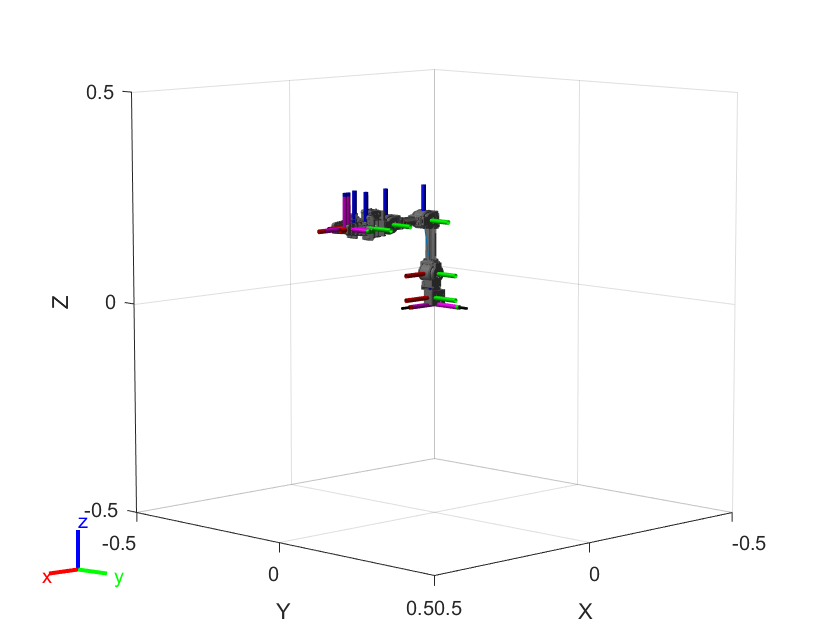

axes = show(robot);

#### Robot Details:

axes.CameraPositionMode = 'auto';
showdetails(robot)

--------------------
Robot: (9 bodies)

 Idx                Body Name                Joint Name                Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                ----------                ----------                ----------------   ----------------
   1                    link1               world_fixed                     fixed                        world(0)   link2(2)  
   2                    link2                    joint1                  revolute                        link1(1)   link3(3)  
   3                    link3                    joint2                  revolute                        link2(2)   link4(4)  
   4                    link4                    joint3                  revolute                        link3(3)   link5(5)  
   5                    link5                    joint4                  revolute                        link4(4)   end_effector_link(6)  gripper_link(7)  gripper_link_sub(8)  end_effect

#### Create a set of desired waypoints from Images:

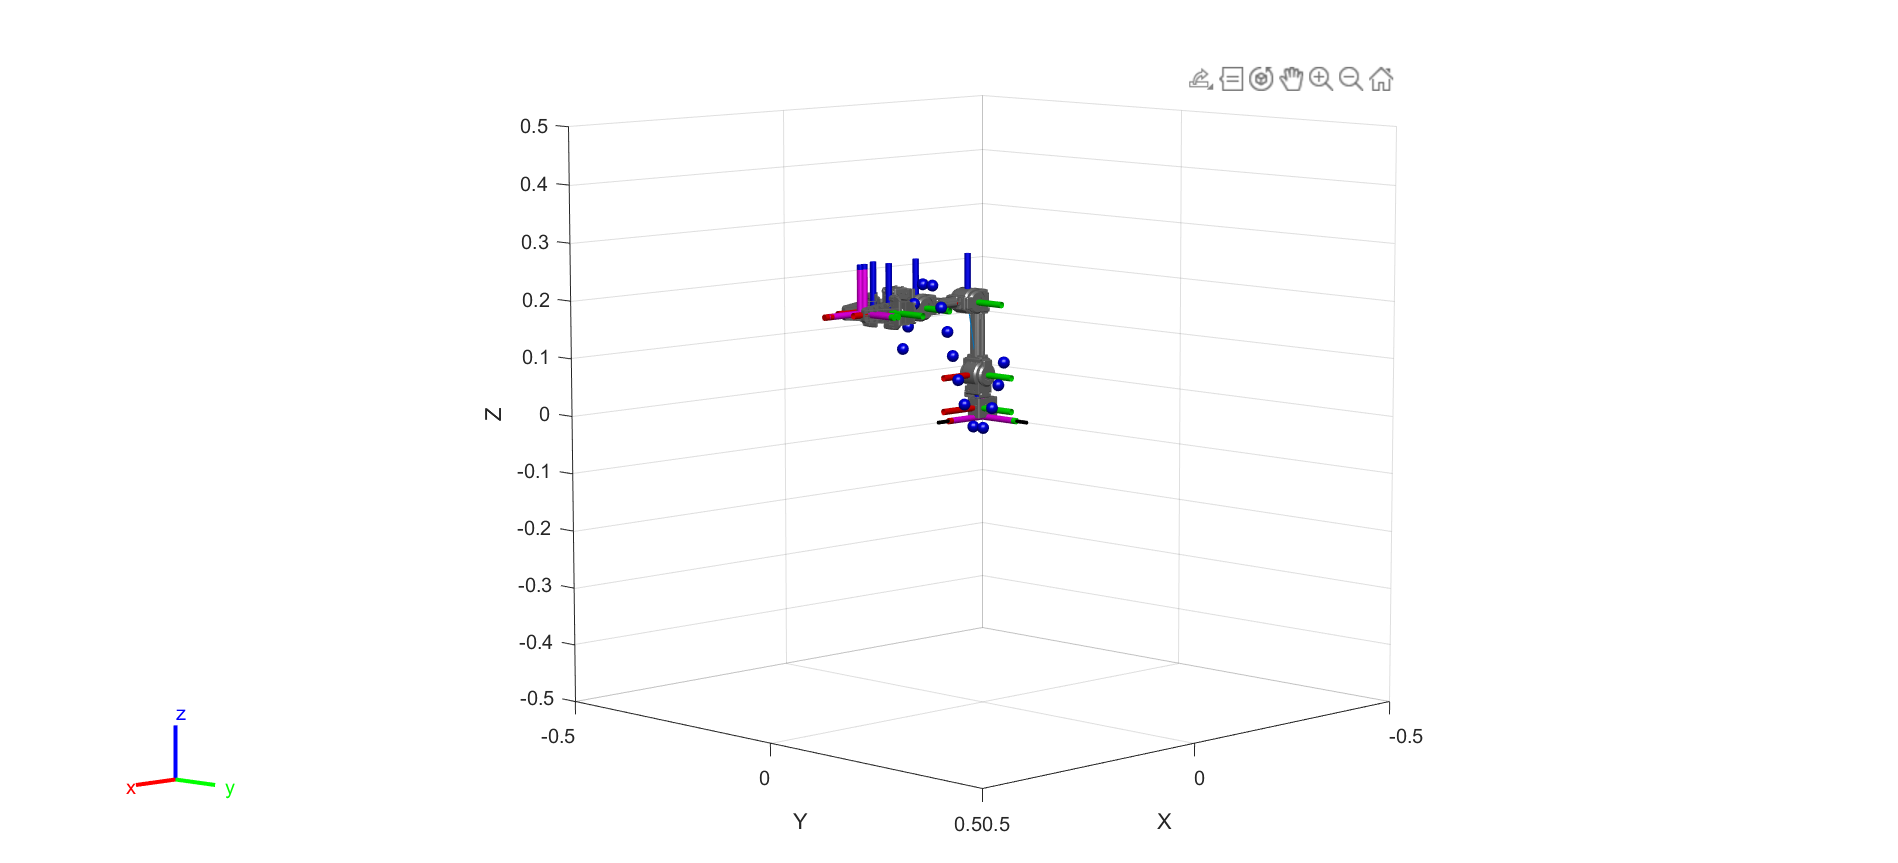

Im = imread('C:\Users\HP\Desktop\pic2points\Images\Plot.png');

T = graythresh(Im);
ImPlot = 'true';
maxNum = 15;
M = pic2point(Im,T,ImPlot,maxNum);  % Function pic2point defined below
M = sortrows(M,'descend');

M = scale(M);           % Function scale defined below
M = nearestSort(M);     % Function nearestSort defined below


wayPoints = [zeros(size(M,1),1), M];
wayPoints(wayPoints(:,1)==0) = .2;
wayPointVels = zeros(size(M,1),3);
exampleHelperPlotWaypoints(wayPoints);

#### Create a smooth trajectory from the waypoints:

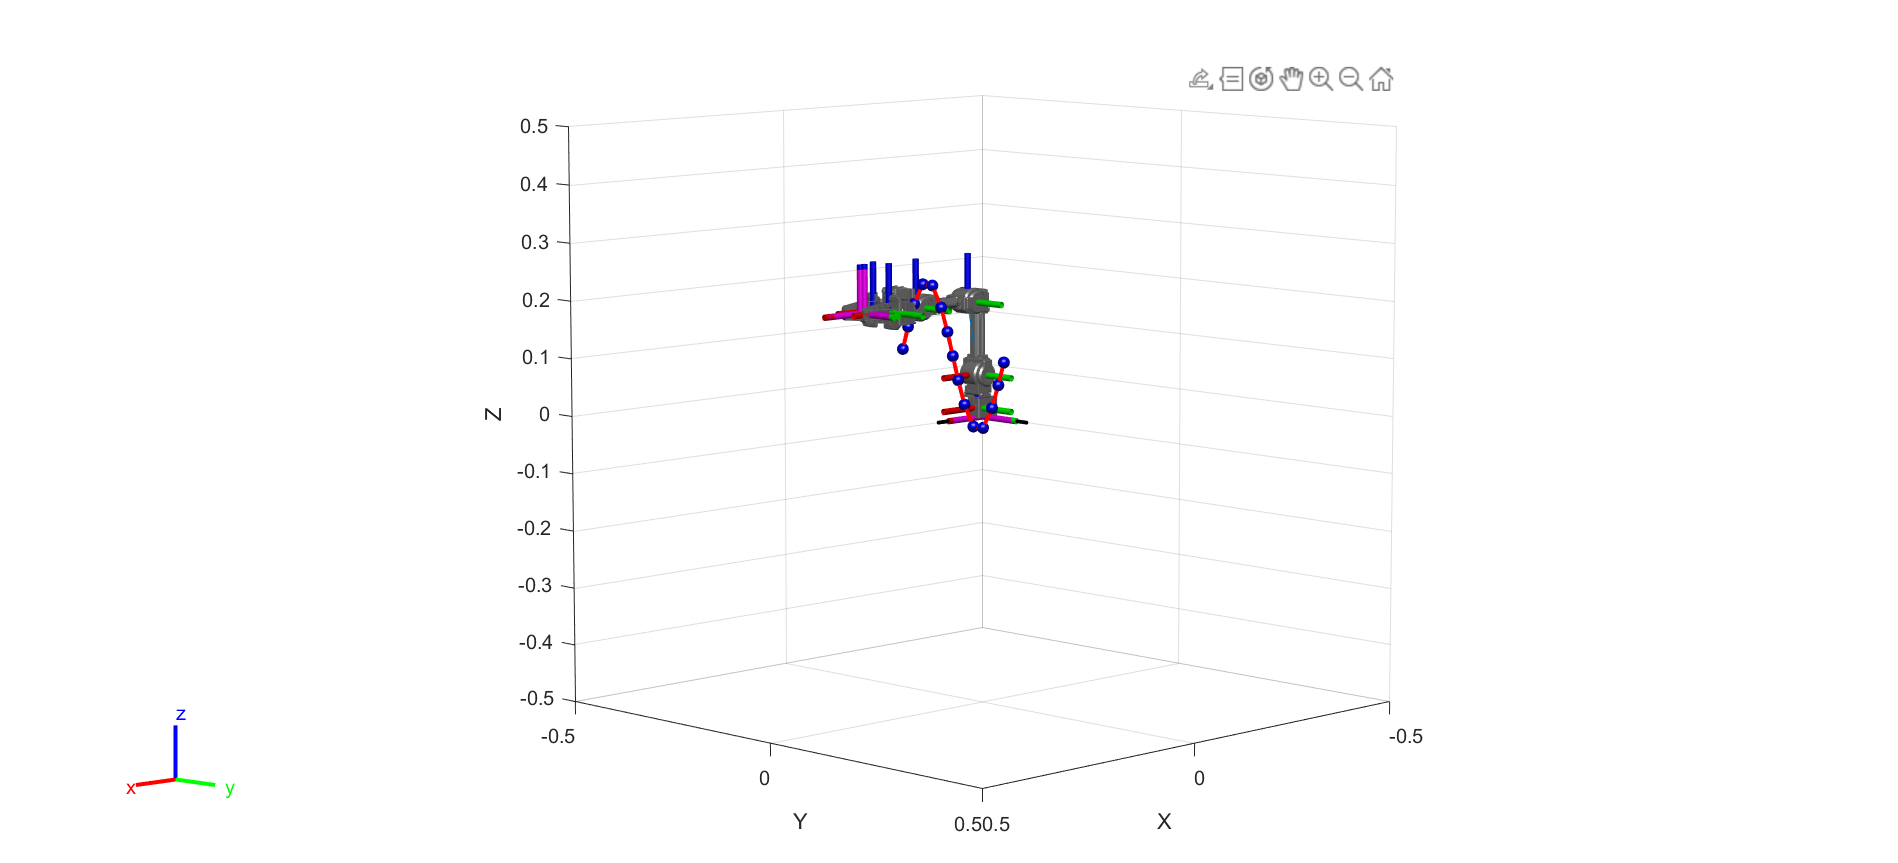


numTotalPoints = size(wayPoints,1)*10;
waypointTime = 0.001;
trajType = 'cubic'; % or 'trapezoidal'
switch trajType
    case 'trapezoidal'
        trajectory = trapveltraj(wayPoints',numTotalPoints,'EndTime',waypointTime);
    case 'cubic'
        wpTimes = (0:size(wayPoints,1)-1)*waypointTime;
        trajTimes = linspace(0,wpTimes(end),numTotalPoints);
        trajectory = cubicpolytraj(wayPoints',wpTimes,trajTimes, ...
                     'VelocityBoundaryCondition',wayPointVels');
end
% Plot trajectory spline and waypoints
hold on
plot3(trajectory(1,:),trajectory(2,:),trajectory(3,:),'r-','LineWidth',2);

#### Perform Inverse Kinematics:


ik = robotics.InverseKinematics('RigidBodyTree',robot);
weights = [0.1 0.1 0 1 1 1];
initialguess = robot.homeConfiguration;

% Call inverse kinematics solver for every end-effector position using the
% previous configuration as initial guess
for idx = 1:size(trajectory,2)
    tform = trvec2tform(trajectory(:,idx)');
    configSoln(idx,:) = ik('end_effector',tform,weights,initialguess);
    initialguess = configSoln(idx,:);
end

#### Visualize robot configurations:

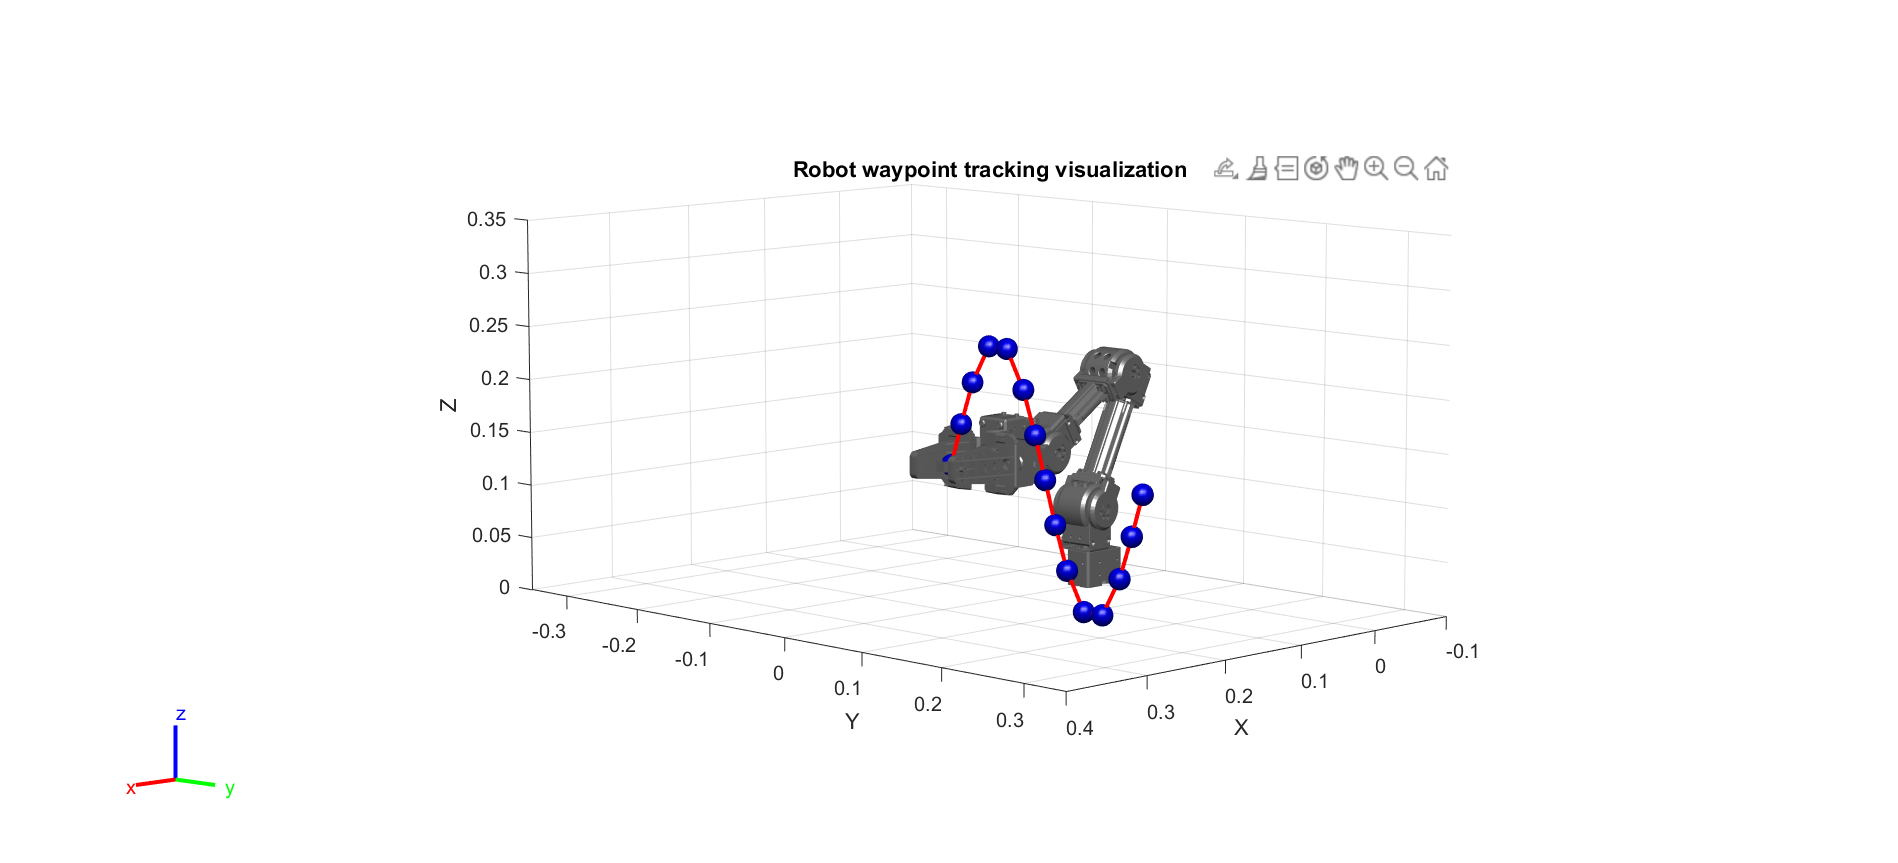

title('Robot waypoint tracking visualization')
axis([-0.1 0.4 -0.35 0.35 0 0.35]);
for idx = 1:size(trajectory,2)
    show(robot,configSoln(idx,:), 'PreservePlot', false,'Frames','off');
    pause(0.1)
end
hold off

#### Functions:

**scale:** Used for scaling the cordinates into the work envolope of the manipulator.

        Parameter: M - x,y coordinates (waypoints in this case)

        Output: M - x,y coordinates after scaling 

**pic2point: **Used for converting images to coordinate points.

        Parameter:  Im - Input image, it can be gray, color or         binary  image. The image can be Double = [0,1] or Unsign integer = [0,255]. The image foreground must be black on white background.

%                    

%  (2)TshV      - Denotes the threshold value for image binarization.

%				  It is between 0~1 and by default is calculated by

%				  graythresh(Im).

%

%  (3)ImPlot    - If the image is a plot, ImPlot must be ‘1’ or ‘true’. 

%                 The image is thinned to 1 pixel width line when ImPlot is 

% 	              true therefore finding the coordinate of drawn line in 

%	              plot would be possible.

%

%  (4)maxNum    - Denotes maximum number of points that should be	

%				  extracted from the image. If all points in the image

%				  are requested, leave the maxNum empty; otherwise enter 

%				  the arbitrary number to select randomly from all points.

%				  Actually it is a random resampling from all point for 

%                 output.

(1) MResult  - Matrix of pixels/points coordinates in the image. MResult

%				  has two columns, first column denotes x-coordinates

%				  and second column is for y-coordinates. 

%				  Number of rows equals to number of points in the image.

function [M] = scale(M)
x = M(:,1);
y = M(:,2);
x = x./(max(x)*4);
y = y./(max(y)*4);
M = [x y];
end

function [MResult] = pic2point(Im,TshV,ImPlot,maxNum)


switch nargin
    case 1
        Pmode = false; % Not a plot
        randomPick = false;
        TshV = graythresh(Im);
    case 2
        Pmode = false; % Not a plot
        randomPick = false;
    case 3
        if strcmpi(ImPlot,'plot')
            Pmode = true; % It is a plot
        else
            Pmode = false; % It is an image
        end
        randomPick = false;
    case 4
        if strcmpi(ImPlot,'plot')
            Pmode = true; % It is a plot
        else
            Pmode = false; % It is an image
        end
        randomPick = true;
end
ImBW=im2bw(Im,TshV);
ImBW=1-ImBW; % When the plot drew by black ink on the white background
if Pmode
    ImBW = bwmorph(ImBW,'thin',Inf);
end
% figure(); imshow(ImBW);
[r,c,v] = find(ImBW==1);
r = size(ImBW,1) - r; % Correct the coordinates from the image
TMresult = [c r];
if randomPick
    Sran = linspace(1,sum(v),maxNum);
    Sran = uint32(Sran);
    %Sran = randperm(sum(v),maxNum);
    MResult = TMresult(Sran',:);
else
    MResult = TMresult;
end 
end

%% Nearest Sort

function [Mnew] = nearestSort(M)

x = M(:,1);
y = M(:,2);
numPoints = size(M,1);

newx = [];
newy =[];

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.08, 1, 0.92]);

% Make a list of which points have been visited
beenVisited = false(1, numPoints);
% Make an array to store the order in which we visit the points.
visitationOrder = ones(1, numPoints);
% Define a filasafe
maxIterations = numPoints + 1;
iterationCount = 1;
% Visit each point, finding which unvisited point is closest.
% Define a current index.  currentIndex will be 1 to start and then will vary.
currentIndex = 1;
while sum(beenVisited) < numPoints && iterationCount < maxIterations
  % Indicate current point has been visited.
  visitationOrder(iterationCount) = currentIndex; 
  beenVisited(currentIndex) = true; 
  % Get the x and y of the current point.
  thisX = x(currentIndex);
  newx = [newx thisX];
  
  thisY = y(currentIndex);
  newy = [newy thisY];
  
  % Compute distances to all other points
  distances = sqrt((thisX - x) .^ 2 + (thisY - y) .^ 2);
  % Don't consider visited points by setting their distance to infinity.
  distances(beenVisited) = inf;
  % Also don't want to consider the distance of a point to itself, which is 0 and would alsoways be the minimum distances of course.
  distances(currentIndex) = inf;
  % Find the closest point.  this will be our next point.
  [minDistance, indexOfClosest] = min(distances);
  % Save this index
  iterationCount = iterationCount + 1;
  % Set the current index equal to the index of the closest point.
  currentIndex = indexOfClosest;
end
Mnew(:,1) = newx;
Mnew(:,2) = newy;
end